# BME3053C : Final Project

## fprintf("Team Name")

## Scanning X-ray Images for Lung Cancer Tumors

#### Authors: Marion Hagstrom, Sarah Scott, Brendan McCue, Karen Villancio-Wolter

#### Course: BME 3053C Computer Applications for BME

#### Term: Spring 2022

#### J. Crayton Pruitt Family Department of Biomedical Engineering

#### University of Florida

#### March 29th, 2022

## Set Up Alexnet for Lung X-rays

Here we establish, Alexnet, a pretrained nueral network, in MATLAB (approved for use). To use Alexnet we have to modify the convoluted nueral network (CNN) to change to specifically reading and recognizing cancer in our X-rays. We learned how to do this from one of UF's AI seminars.

CNN = alexnet;
analyzeNetwork(CNN)
layrs = CNN.Layers; 
layrs(23) = fullyConnectedLayer(2); 
layrs(24) = softmaxLayer(); 
layrs(25) = classificationLayer("Classes", ...
    {'Mass' 'No Mass'}); 

## Splitting data for training and testing

Here we load our images with the the labels healthy and mass. They have to be 277x277x3 because Alexnet needs this size as its input. We then split our data into training and testing. Based on literature and in-class assignments we chose 80% training and 20% testing randomly assigned.

correctsize = @(imagefilename)imresize(imread(imagefilename), [227 227]);
unzippedfile = 'FinalFinal';
images = imageDatastore(unzippedfile, 'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames', 'ReadFcn', correctsize);
[training, testing] = splitEachLabel(images, 0.8, 'randomize'); 

## Alexnet Training

We chose to use a Mini-Batch Gradient Descent so 1 < Batch Size < Size of Training Set therefore we chose 2 as our batch number (evenly divides into our number of images). Epoch should be large so we went with 100 but this can be edited based on accuracy level desired. 

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |       50.00% |       1.8290 |      1.0000e-04 |
|       3 |          50 |       00:01:02 |      100.00% |       0.1788 |      1.0000e-04 |
|       5 |         100 |       00:01:59 |       50.00% |       1.3092 |      1.0000e-04 |
|       7 |         150 |       00:02:53 |      100.00% |       0.0330 |      1.0000e-04 |
|       9 |         200 |       00:03:44 |      100.00% |       0.0973 |      1.0000e-04 |
|      11 |         250 |       00:04:33 |      100.00% |       0.1227 |      1.0000e-04 |
|      13 |         300 |  

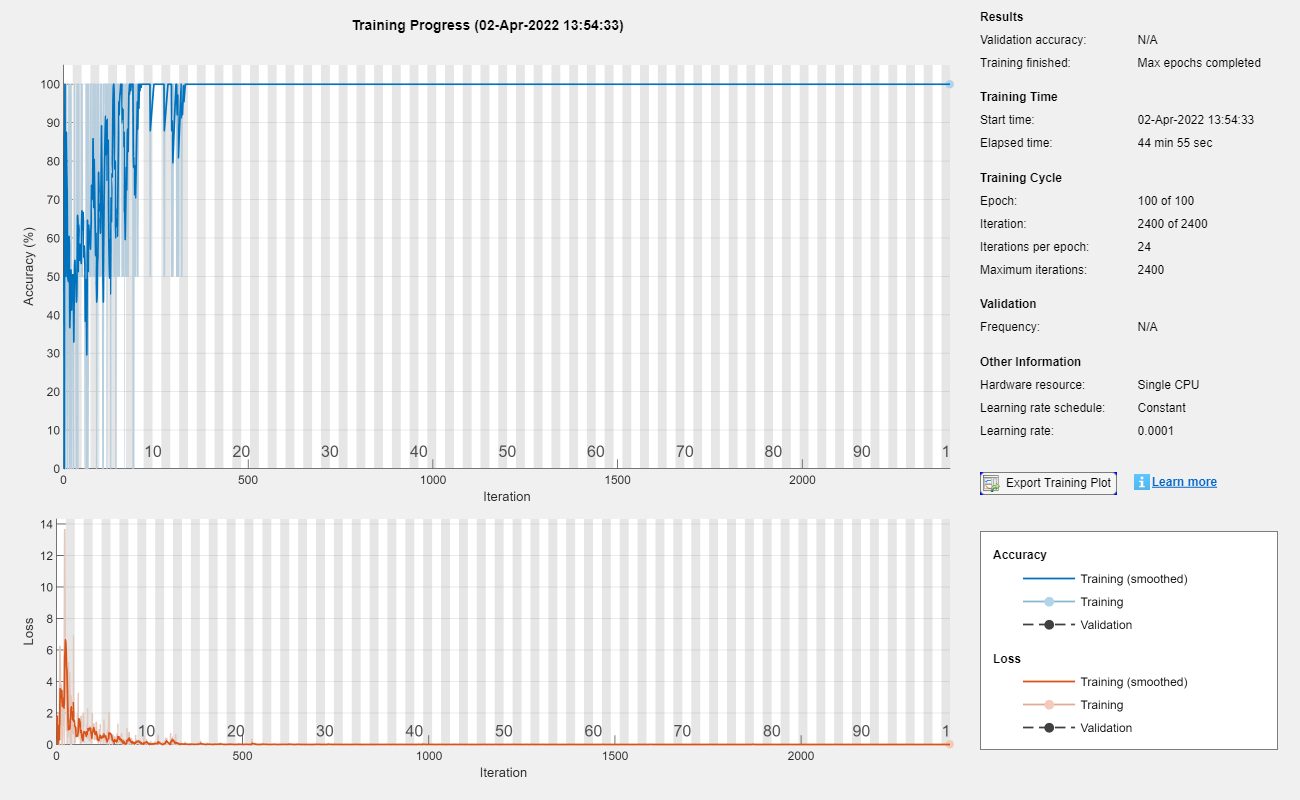

trainingopt = trainingOptions('sgdm', 'InitialLearnRate', 0.0001, ...
    'MaxEpochs', 100, 'MiniBatchSize', 2 ,'Plots', ...
    'training-progress', 'ExecutionEnvironment',"auto"); 
network = trainNetwork(training, layrs, trainingopt); 

## Alexnet Testing

Here we use a confusion matrix to analyze our CNN's accuracy.

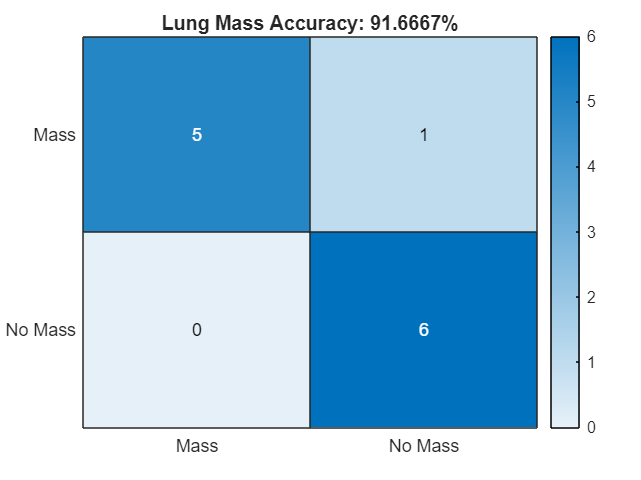

label_prediction = classify(network, testing);
acc = sum(label_prediction == testing.Labels) / numel(label_prediction);
[confusion, x] = confusionmat(testing.Labels, label_prediction);
figure
heatmap(x, x, confusion);
title("Lung Mass Accuracy: " + acc*100 + "%") 

## Optional, Specific Image

% specificxray = imread('______'); 
% imshow(specificxray); 
% new = imresize(specificxray, [227 227]); 
% classify(CNN, new) 